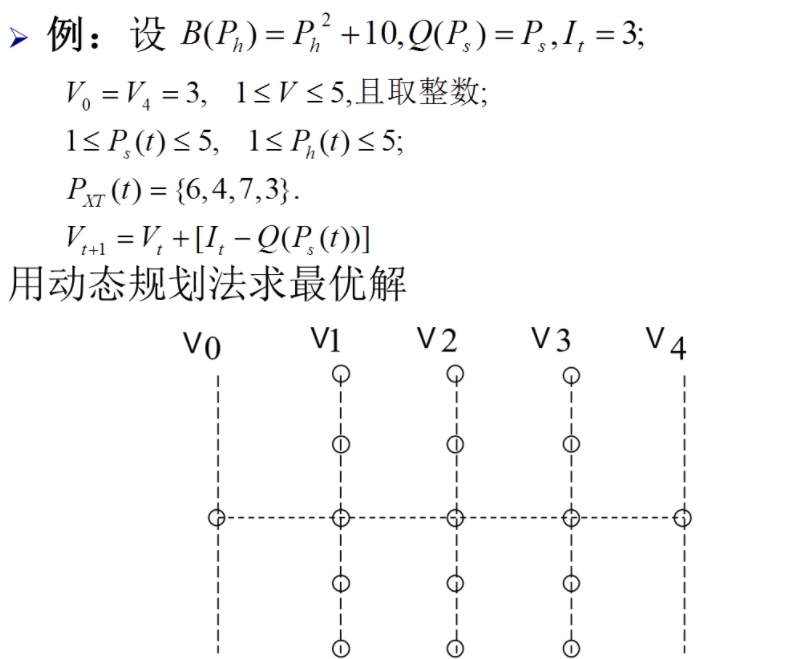

clc;clear
Pxt=[6 4 7 3];
% B=@(Ph)Ph^2+10; %B(Ph)的匿名函数，语法为fhandle=@(arglist) expression
stage_num=size(Pxt,2); %阶段为4
V=5; %每个阶段的选择为5，物理意义是用水量为1-5
I=3;
start_V=3;
stage(stage_num+1).V=3;

% V_next=V_end;
% 使用倒退的动态规划
% 初始大循环之前的条件，也就是stage(end-1)的V和Q
% temp=zeros(V,3);
% for i=1:V
%     Q=i+I-stage(end).V;
%     temp(i,1)=MYFUN_DP6(Q,Pxt(end));
%     temp(i,2)=i;
%     temp(i,3)=Q;
% end
% temp_index=temp(:,1)~=Inf;
% stage(end-1).Value=temp(temp_index,1);
% stage(end-1).V=temp(temp_index,2);
% stage(end-1).Q=temp(temp_index,2);
stage(end).Value=0;
stage(end).Q=[];
% stage(end).Q=temp(temp_index,2);
% 大循环
for i=stage_num:-1:2
    temp_num=length(stage(i+1).Value);
    for j=V:-1:1
        storage=zeros(temp_num,3);
        for k=1:temp_num
            V_next=stage(i+1).V(k);
            Q=j+I-V_next;
            storage(k,1)=MYFUN_DP6(Q,Pxt(i))+stage(i+1).Value(k);
            storage(k,2)=j;
            storage(k,3)=Q;
        end
        temp_obj=min(storage(:,1));
        if temp_obj~=inf
            temp_index=find(storage(:,1)==temp_obj);
            temp_count=length(temp_index);
            stage(i).Value(end+1:end+temp_count)=storage(temp_index,1);
            stage(i).V(end+1:end+temp_count)=storage(temp_index,2);
            stage(i).Q(end+1:end+temp_count)=storage(temp_index,3);
        end
    end
end

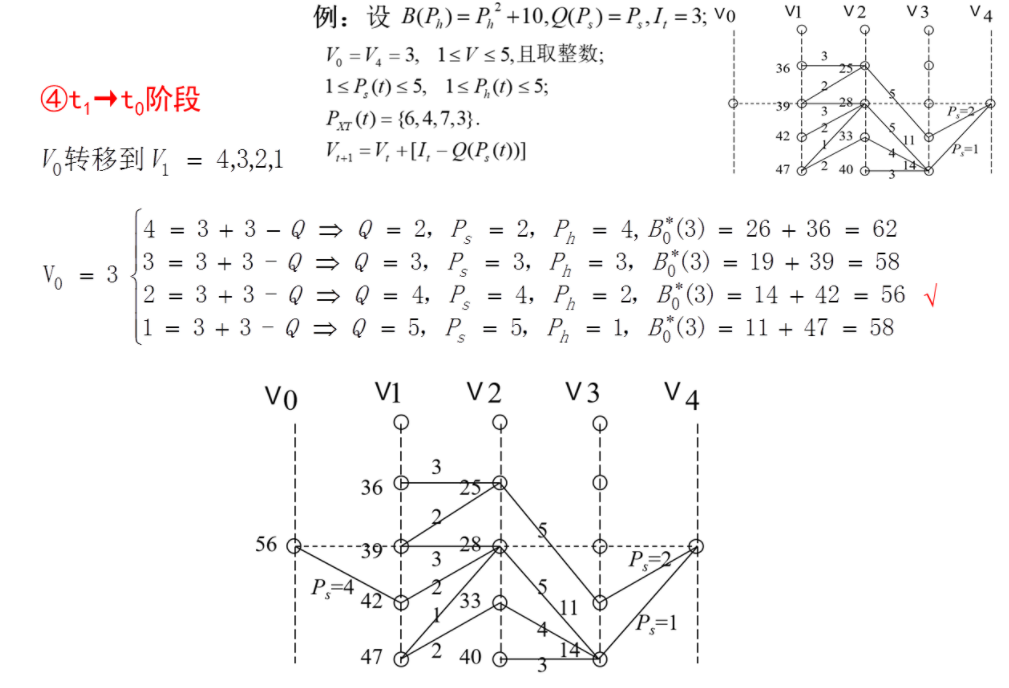

%stage==1时候
i=1;
temp_num=length(stage(i+1).Value);
% for j=V:-1:1
V=start_V;
storage=zeros(temp_num,3);
for k=1:temp_num
    V_next=stage(i+1).V(k);
    Q=V+I-V_next;
    storage(k,1)=MYFUN_DP6(Q,Pxt(i))+stage(i+1).Value(k);
    storage(k,2)=V;
    storage(k,3)=Q;
end
temp_obj=min(storage(:,1));
if temp_obj~=inf
    temp_index=find(storage(:,1)==temp_obj);
    temp_count=length(temp_index);
    stage(i).Value(end+1:end+temp_count)=storage(temp_index,1);
    stage(i).V(end+1:end+temp_count)=storage(temp_index,2);
    stage(i).Q(end+1:end+temp_count)=storage(temp_index,3);
end